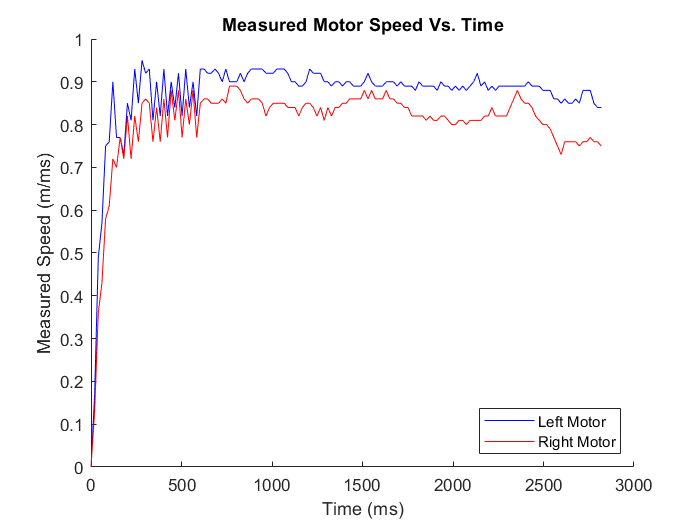

motor_parameter_estimation_data = [
    0.00,0.00;
    0.15,0.15;
    0.50,0.49;
    0.64,0.61;
    0.80,0.75;
    0.77,0.73;
    0.88,0.81;
    0.81,0.76;
    0.90,0.84;
    0.82,0.77;
    0.90,0.85;
    0.82,0.77;
    0.93,0.88;
    0.94,0.88;
    0.94,0.86;
    0.93,0.86;
    0.93,0.86;
    0.93,0.86;
    0.92,0.85;
    0.93,0.86;
    0.93,0.86;
    0.93,0.86;
    0.94,0.86;
    0.93,0.86;
    0.93,0.86;
    0.94,0.88;
    0.94,0.86;
    0.94,0.88;
    0.94,0.88;
    0.92,0.85;
    0.93,0.86;
    0.94,0.86;
    0.94,0.88;
    0.94,0.86;
    0.93,0.85;
    0.94,0.86;
    0.93,0.85;
    0.94,0.88;
    0.94,0.86;
    0.95,0.88;
    0.94,0.86;
    0.94,0.86;
    0.94,0.86;
    0.93,0.85;
    0.92,0.85;
    0.92,0.85;
    0.94,0.86;
    0.94,0.88;
    0.93,0.86;
    0.93,0.86;
    0.93,0.88;
    0.94,0.88;
    0.95,0.88;
    0.94,0.88;
    0.95,0.89;
    0.94,0.86;
    0.95,0.88;
    0.94,0.88;
    0.94,0.88;
    0.93,0.86;
    0.93,0.86;
    0.94,0.88;
    0.94,0.88;
    0.94,0.85;
    0.95,0.88;
    0.95,0.88;
    0.94,0.86;
    0.94,0.88;
    0.94,0.86;
    0.94,0.88;
    0.95,0.85;
    0.94,0.86;
    0.94,0.86;
    0.93,0.85;
    0.94,0.86;
    0.94,0.86;
    0.95,0.88;
    0.94,0.88;
    0.94,0.85;
    0.94,0.86;
    0.95,0.86;
    0.95,0.88;
    0.95,0.88;
    0.95,0.89;
    0.94,0.88;
    0.94,0.86;
    0.95,0.89;
    0.95,0.89;
    0.95,0.89;
    0.92,0.86;
    0.94,0.89;
    0.95,0.89;
    0.95,0.89;
    0.95,0.90;
    0.95,0.89;
    0.94,0.89;
    0.95,0.89;
    0.94,0.88;
    0.95,0.88;
    0.95,0.88;
    0.94,0.88;
    0.95,0.86;
    0.95,0.88;
    0.93,0.85;
    0.94,0.86;
    0.95,0.86;
    0.94,0.86;
    0.95,0.86;
    0.94,0.86;
    0.94,0.88;
    0.95,0.88;
    0.95,0.86;
    0.97,0.86;
    0.95,0.86;
    0.94,0.86;
    0.94,0.88;
    0.94,0.88;
    0.94,0.86;
    0.95,0.88;
    0.94,0.85;
    0.94,0.86;
    0.94,0.88;
    0.94,0.86;
    0.95,0.88;
    0.94,0.88;
    0.95,0.88;
    0.95,0.89;
    0.94,0.88;
    0.94,0.86;
    0.94,0.88;
    0.95,0.88;
    0.95,0.89;
    0.95,0.89;
    0.93,0.85;
    0.94,0.88;
    0.94,0.88;
    0.94,0.88;
    0.95,0.89;
    0.97,0.89;
    0.95,0.88;
    0.95,0.89;
    ];

motorL = calibration_data(:,1);
motorR = calibration_data(:,2);
t = linspace(0, 3000, 150);
t = t(1:141)';

transient_motorR = motorR(1:25);
transient_motorL = motorL(1:25);
steady_motorR = motorR(25:end);
steady_motorL = motorL(25:end);
transient_t = t(1:25);
steady_t = t(25:end);

figure
clf
hold on
plot(t, motorL, 'b')
plot(t, motorR, 'r')
ylabel("Measured Speed (m/ms)")
xlabel("Time (ms)")
legend("Left Motor", "Right Motor", 'Location', 'southeast')
title("Measured Motor Speed Vs. Time")


syms s k tau m
m = (k/tau) / (s+(1/tau));
laplace(m)

$$ans = \left\{ \begin{array}{cl} \frac{k\,\mathrm{e}\,\text{expint}\left(1\right)}{s} & \text{ if }0<s\\ -\frac{k\,\mathrm{e}\,\left(\frac{\log\left(\frac{1}{s}\right)}{2}-\log\left(1\right)+\frac{\log\left(s\right)}{2}-\text{expint}\left(1\right)\right)}{s} & \text{ if }\neg 0\leq s \end{array}\right.$$